#  Simulation Analysis Live Script

## Dechirped Signal

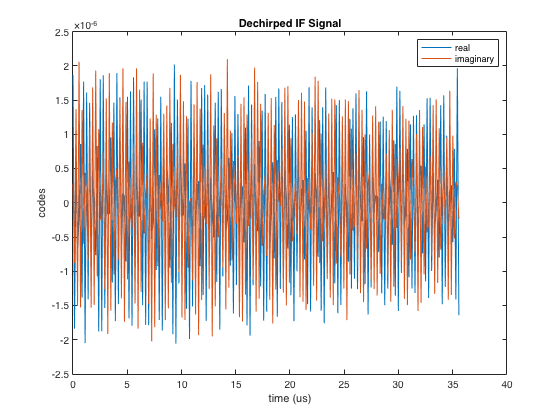

if_sig = out.dechirped_signal(:,:,1);
hann_window = hann(simulator.Victim.ADC_Samples);

if_sig_windowed = if_sig .* hann_window;

t_increment = 1/(simulator.Victim.ADC_SampleRate_MSps * 1e6);
t = (0:t_increment: simulator.Victim.ADC_Samples * t_increment - t_increment) * 1e6;

ranges = 0:simulator.Victim.Range_Res_m : simulator.Victim.Range_Res_m * simulator.Victim.ADC_Samples - simulator.Victim.Range_Res_m;

plot(t,real(if_sig),t,imag(if_sig))
xlabel('time (us)');
ylabel('codes');
title_str = sprintf('Dechirped IF Signal');
title(title_str);
legend('real','imaginary');

## Range Doppler Processing

### Out of the Range-Doppler Response Block

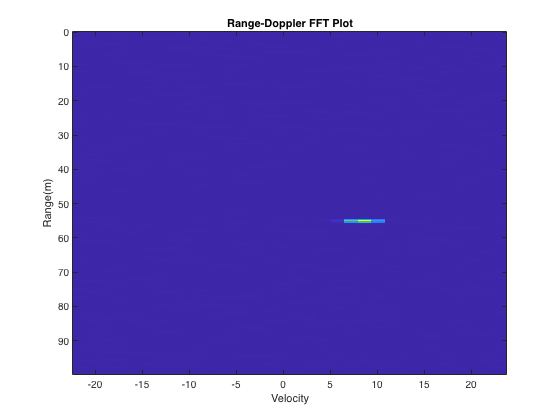

velocities = flip(out.velocity_bins); %velocities are coming out flipped for some reason
ranges = out.range_bins;
range_doppler_response = abs(out.range_doppler_response);

% subplot(2,1,1)
% surf(velocities,ranges, range_doppler_response);
% title('Range-Doppler FFT Plot - As Surf')
% xlabel('Velocity')
% ylabel('Range(m)')
% zlabel('Magnitude (dB)')

% subplot(2,1,2)
imagesc(velocities,ranges, range_doppler_response);
title_str = sprintf('Range-Doppler FFT Plot');
title(title_str);
xlabel('Velocity')
ylabel('Range(m)')

### Computing using the radar cube that's been created

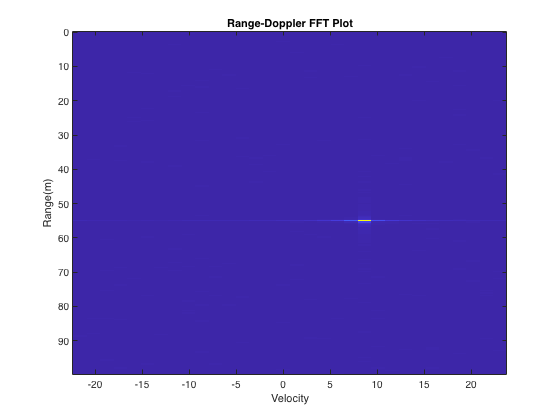

radar_cube = out.radar_cube;

%need to employ windowing as well on this
range_doppler_response = abs(fftshift(fft(fft(radar_cube).').',2));
range_doppler_response = abs(fftshift(fft2(radar_cube),2));
imagesc(velocities,ranges, range_doppler_response);
title_str = sprintf('Range-Doppler FFT Plot');
title(title_str);
xlabel('Velocity')
ylabel('Range(m)')

## CA CFAR Algorithm

detections = out.CFAR_detections;
clusters = out.cluster_detections;
range_estimates = out.range_estimates;
velocity_estimates = out.velocity_estimates;